# **Analysis 1 F001: Live cell analysis**

**Testing for:**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%imagePath = '';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    'siCtrl',2,2:6,1:9,[0 0 0]; %1      
    'siCCNA2',3,2:6,1:9,[0 0 0]; %1      
    
};



load([dataDir filesep 'D121_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 11;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    cdkGate = false(length(dat.POI(:,1)),1);
%     apcGate = false(length(dat.POI(:,1)),1);
    crlGate = false(length(dat.POI(:,1)),1);
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) + 1* framesPerHr <= numFrames
            cdkGate(n) = dat.cdk(n,dat.POI(n,1) - 1 * framesPerHr) > 1 &...
                dat.cdk(n,dat.POI(n,1) - 1* framesPerHr) < 2.2 & ...
                dat.cdk(n,dat.POI(n,1) + 1 * framesPerHr) < 0.9;
        end
%         if dat.POI(n,2) + round(5*framesPerHr) <= numFrames 
%             apcGate(n) = dat.apcNuc(n,dat.POI(n,2) + round(5*framesPerHr)) > 40 ;
%         end
        if dat.POI(n,3) + round(4*framesPerHr) <= numFrames 
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,3) + round(4* framesPerHr)) < .5 ;
        end

    end
%     S(i).apcGate = apcGate;
    S(i).cdkGate = cdkGate;
    S(i).crlGate = crlGate;
%         S(i).cdkHighGate = cdkHighGate;

end

**Mean cdk traces post CRL4**

conds = [1 2];
timeGate = [ 0 6];
POI_align = 3;
figure('unit','inches','position',[0 0 4 4])
hold on
cols = lines(2);
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
       data.crlGate & data.POI_realtime(:,3) - data.POI_realtime(:,1) > 5 & data.POI_realtime(:,3) - data.POI_realtime(:,1) < 6 ;
    ydata = smoothdata(data.cdk(inds,:),5,'sgolay');
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
%     errorbar((frames)/framesPerHr,medSig,2*semCRL,'LineWidth',1.5);
        shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',cols(i,:),'LineWidth',1});

%         [frames, medSig, semCRL] =get_median_trace(ydata,POI,1);
%         plot((frames)/framesPerHr,medSig,'LineWidth',1.5);
sum(inds)
end

ans = 115

ans = 110

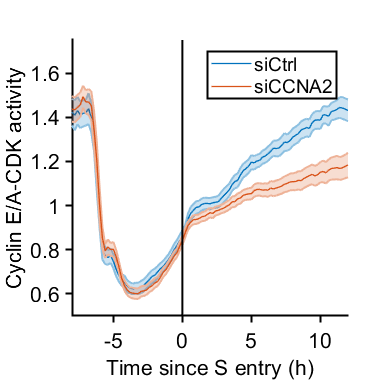


ylabel({'Cyclin E/A-CDK activity'});xlabel('Time since S entry (h)');
axis square
%legend(conditions(conds,1));
legend(conditions(conds,1))
xlim([-8 12]); 
ylim([.5 1.75]);
% %ylim([.5 1.5])
vline([0],'k')
print_pdf([pwd() '\Figs\CDK_A2.pdf'])

## **Plot traces aligned**

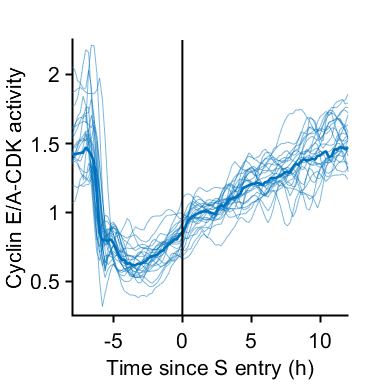

rng(2)
conds=[1];
poiAlign = [3];
alignNames = {'CRL4 on'};
cols = [0 113 188]/255;
for p = 1:length(poiAlign)
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
    hold on
    for i=1:length(conds)
        data = S(conds(i));
        inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
       data.crlGate & data.cdkGate & data.POI_realtime(:,3) - data.POI_realtime(:,1) > 5 & data.POI_realtime(:,3) - data.POI_realtime(:,1) < 6 ;
        indplot = (data.traceStats(:,2)-data.POI(:,poiAlign(p)))/framesPerHr > 12;        cells = find(inds);
        cellsplot = find(inds & indplot);
        for numcell = randsample(cellsplot,min([25 length(cells)]))'
            timeAligned = (xFrames-data.POI(numcell,poiAlign(p)))/framesPerHr;
            patchline(timeAligned(1:end-1),nansmoothm(data.cdk(numcell,1:end-1),7,'sgolay'),'edgecolor',cols(i,:),'LineWidth',.5,'edgealpha',.5);
            %([conditions{conds(i),1} ' aligned to ' alignNames{(p)}]);
            ylabel('Cyclin E/A-CDK activity');
            ylim([.25 2.25]);
            xlim([-8 12]);
%             xticks([-8:2:4])
            xlabel('Time since S entry (h)');
        end
        [frames, medSig, semCRL] =get_median_trace(data.cdk(cells,:),data.POI(cells,poiAlign(p)),0);
        plot((frames)/framesPerHr,medSig,'k','LineWidth',2,'Color',cols(i,:))
%         cells = length(cells)
        vline(0,'k')
    end
    hold off
    axis square
end

print_pdf([pwd() '\Figs\example_traces'])